clc; clear; close all; 
digits(6)

axial_file1= readmatrix("C:\Users\HP\Downloads\Calibration_data\Axial_232p4_load.csv");
axial_raw_v_file1= axial_file1(:,2);
axial_v_file1=mean(axial_raw_v_file1);
axial_load1= 232.4/1000 ;

axial_file2= readmatrix("C:\Users\HP\Downloads\Calibration_data\Axial_718p4_load.csv");
axial_raw_v_file2= axial_file2(:,2);
axial_v_file2=mean(axial_raw_v_file2);
axial_load2= 718.4/1000;

axial_file3= readmatrix("C:\Users\HP\Downloads\Calibration_data\Axial_1507p6_load.csv");
axial_raw_v_file3= axial_file3(:,2);
axial_v_file3=mean(axial_raw_v_file3);
axial_load3= 1507.6/1000;

axial_file4= readmatrix("C:\Users\HP\Downloads\Calibration_data\Axial_2267p7_load.csv");
axial_raw_v_file4= axial_file4(:,2);
axial_v_file4=mean(axial_raw_v_file4);
axial_load4= 2267.7/1000;

axial_file5= readmatrix("C:\Users\HP\Downloads\Calibration_data\Axial_zero_load.csv");
axial_raw_v_file5= axial_file5(:,2);
axial_v_file5=mean(axial_raw_v_file5);
axial_load5= 0;

axial_loads= [axial_load1 axial_load2 axial_load3 axial_load4 axial_load5 ]

axial_loads =     0.2324    0.7184    1.5076    2.2677         0


axial_v= [axial_v_file1 axial_v_file2 axial_v_file3 axial_v_file4 axial_v_file5]

axial_v = 1.0e-04 *

   -0.0562   -0.2675   -0.6095   -0.9404    0.0437


normal_file1= readmatrix("C:\Users\HP\Downloads\Calibration_data\normal_232p4_load.csv");
normal_raw_v_file1= normal_file1(:,2);
normal_v_file1=mean(normal_raw_v_file1);
normal_load1= 232.4/1000 ;


normal_file2= readmatrix("C:\Users\HP\Downloads\Calibration_data\normal_718p4_load.csv");
normal_raw_v_file2= normal_file2(:,2);
normal_v_file2=mean(normal_raw_v_file2);
normal_load2= 718.4/1000;


normal_file3= readmatrix("C:\Users\HP\Downloads\Calibration_data\normal_1507p6_load.csv");
normal_raw_v_file3= normal_file3(:,2);
normal_v_file3=mean(normal_raw_v_file3);
normal_load3= 1507.6/1000;


normal_file4= readmatrix("C:\Users\HP\Downloads\Calibration_data\normal_2267p7_load.csv");
normal_raw_v_file4= normal_file4(:,2);
normal_v_file4=mean(normal_raw_v_file4);
normal_load4= 2267.7/1000;


normal_file5= readmatrix("C:\Users\HP\Downloads\Calibration_data\normal_zero_load.csv");
normal_raw_v_file5= normal_file5(:,2);
normal_v_file5=mean(normal_raw_v_file5);
normal_load5= 0;

normal_loads= -[normal_load1 normal_load2 normal_load3 normal_load4 normal_load5 ]

normal_loads =    -0.2324   -0.7184   -1.5076   -2.2677         0


normal_v= [normal_v_file1 normal_v_file2 normal_v_file3 normal_v_file4 normal_v_file5]

normal_v = 1.0e-03 *

   -0.1134   -0.1339   -0.1671   -0.1992   -0.1037


poly_axial=polyfit(axial_v,axial_loads,1)

poly_axial = 1.0e+04 *

   -2.3040    0.0000


poly_normal=polyfit(normal_v,normal_loads,1)

poly_normal = 1.0e+04 *

    2.3734    0.0002


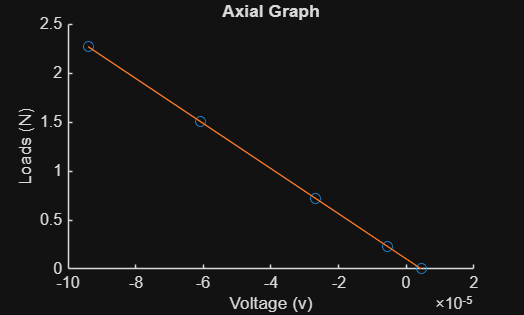


figure
scatter(axial_v,axial_loads)
hold on
plot(axial_v, polyval(poly_axial,axial_v))
title("Axial Graph")
xlabel("Voltage (v)")
ylabel("Loads (N)")

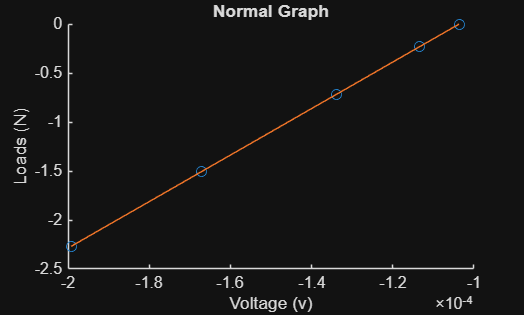


figure
scatter(normal_v,normal_loads)
hold on
plot(normal_v, polyval(poly_normal,normal_v))
title("Normal Graph")
xlabel("Voltage (v)")
ylabel("Loads (N)")

axial_tunnel_off_file= readmatrix("C:\Users\HP\Downloads\windtunnelmeasurementssec2bn13\Axial_tunnel_off_AOA_-5.3_DynP_0.csv");
axial_tunnel_on_file= readmatrix("C:\Users\HP\Downloads\windtunnelmeasurementssec2bn13\Axial_Sec_2_BN_13_AOA_-5.3_DynP_145.1.csv");

normal_tunnel_off_file= readmatrix("C:\Users\HP\Downloads\windtunnelmeasurementssec2bn13\normal_tunnel_off_AOA_-5.3_DynP_0.csv");
normal_tunnel_on_file= readmatrix("C:\Users\HP\Downloads\windtunnelmeasurementssec2bn13\normal_Sec_2_BN_13_AOA_-5.3_DynP_145.1.csv");

axial_tunnel_off_v= mean(axial_tunnel_off_file(:,2));
axial_tunnel_on_v= mean(axial_tunnel_on_file(:,2));

normal_tunnel_off_v= mean(normal_tunnel_off_file(:,2));
normal_tunnel_on_v= mean(normal_tunnel_on_file(:,2));

axial_tunnel_off_load= polyval(poly_axial,axial_tunnel_off_v);
axial_tunnel_on_load= polyval(poly_axial,axial_tunnel_on_v);

normal_tunnel_off_load= polyval(poly_normal,normal_tunnel_off_v);
normal_tunnel_on_load= polyval(poly_normal,normal_tunnel_on_v);


% Net Normal and Axial Loads
net_axial_load= 9.8*(axial_tunnel_on_load -  axial_tunnel_off_load)

net_axial_load = 1.8256

net_normal_load= 9.8*(normal_tunnel_on_load - normal_tunnel_off_load)

net_normal_load = 0.0290

% Calculate Lift and Drag
alpha=-5.3;
lift= net_normal_load * cosd(alpha) - net_axial_load * sind(alpha)

lift = 0.1975

Drag= net_normal_load * sind(alpha) + net_axial_load * cosd(alpha)

Drag = 1.8151

X= -net_axial_load

X = -1.8256

Z= -net_normal_load

Z = -0.0290

q_inf=145.1;
s = 0.13 * 0.80;
CL= lift/q_inf/s

CL = 0.0131

CD= Drag/q_inf/s

CD = 0.1203

CN= net_normal_load/q_inf/s

CN = 0.0019

CA= net_axial_load/q_inf/s

CA = 0.1210

CX=-X/q_inf/s

CX = 0.1210

CZ=Z/q_inf/s

CZ = -0.0019

% Errors in Experiment 
% 1. Vibrations of the body due to mechanism 
% 2. Model is out of wind tunnel not in 
% 3. Horizontal Planes are not perfectly horizontal 
% 4. Noises in sensors due to sensetivity and natural environment 
% 5. Fixation of manometer leads to uncertain readings 
% 6. Ratio of body to wind tunnel is bigger than normal
% 7. Drag due to mechanism 
% 8. The model and other plates are not perfectly parallel 
% 9. Some loses in pressure in pipes and structure of wind tunnel 
% 10. Flow is not perfectly streamlines, maybe there are some Turbulence

% Correction Equations
delta_w= -0.25;                 % Standard Assumption 
AR= 0.80^2/s;     
D= 1.6*2;                       % Assume wind tunnel is 1.6m height and 2m width
epsilon = (s/D)*(CD-CL^2*((1/pi/AR)-delta_w*s/D))

epsilon = 0.0039

q_inf_correct= q_inf*(1+epsilon)^2

q_inf_correct = 146.2366

CL_correct=lift/q_inf_correct/s

CL_correct = 0.0130

alpha_correct= -(delta_w*(s/D)*CL_correct -alpha)

alpha_correct = -5.2999

CD_correct= -(delta_w*(s/D)*(CL_correct)^2 - CD)

CD_correct = 0.1203